# DOA估计综述

## DBF，均匀阵列与最小冗余与随机非均匀阵列的dbf测角效果对比

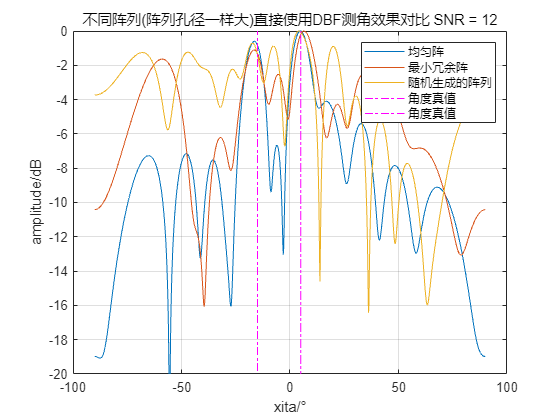

clear all; clc; clf;
%构造阵列

array_mmr = [0 1 2 6 10 13];        %6阵元最小冗余阵
array_uni = 0:1:array_mmr(end);     %同样孔径下的均匀阵列

arraylen  = length(array_mmr); 
array_rand = zeros(1,arraylen);
array_rand(1) = 0;
array_rand(end) = array_mmr(end);
%生成一个 [1 array_mmr(end)]中间的不存在重复元素的长为arraylen-2的随机阵列？：
len_rand = arraylen-2;
while 1
    buffer = ( floor( rand(1,len_rand)* (array_mmr(end)-1) ) + 1 );
    arraytmp = unique(buffer);
    if length(arraytmp) == len_rand
        break;
    end
end
array_rand(2:end-1) = arraytmp;


%构造信号
% theta = 0;     %目标角度
theta = [5, -15];  %多个目标时？

dd     = 0.5;   %均匀间隔
snap   = 1;     %快拍数
snr    = 12; 

numstarget = length(theta);
S = rand(numstarget,snap);

A_uni = exp(-1i*2*pi*dd*sind(theta).*array_uni.'); x_uni = A_uni*S;  x_uni = awgn(x_uni,snr); 
A_mmr = exp(-1i*2*pi*dd*sind(theta).*array_mmr.');  A_mmr = awgn(A_mmr,snr);  x_mmr = A_mmr*S;  x_mmr = awgn(x_mmr,snr); 
A_rand = exp(-1i*2*pi*dd*sind(theta).*array_rand.'); A_rand = awgn(A_rand,snr);  x_rand = A_rand*S;  x_rand = awgn(x_rand,snr); 


%使用dbf测角
thetascan = linspace(-90,90,1024);
a_uni = exp(1i*2*pi*dd*sind(thetascan).'*array_uni);
a_mmr = exp(1i*2*pi*dd*sind(thetascan).'*array_mmr);
a_rand = exp(1i*2*pi*dd*sind(thetascan).'*array_rand);

p_uni = x_uni.'*a_uni.';  p_uni = 10*log10(abs(p_uni)./max(abs(p_uni)));
p_mmr = x_mmr.'*a_mmr.';  p_mmr = 10*log10(abs(p_mmr)./max(abs(p_mmr)));
p_rand = x_rand.'*a_rand.'; p_rand = 10*log10(abs(p_rand)./max(abs(p_rand)));

figure(1)
plot(thetascan,p_uni);hold on;
plot(thetascan,p_mmr);plot(thetascan,p_rand);
% plot([theta,theta],ylim,'m-.');
plot([theta(1),theta(1)],ylim,'m-.');plot([theta(2),theta(2)],ylim,'m-.');
xlabel('xita/°');ylabel('amplitude/dB');title(['不同阵列(阵列孔径一样大)直接使用DBF测角效果对比 SNR = ' num2str(snr)]);
legend('均匀阵','最小冗余阵','随机生成的阵列','角度真值','角度真值');
hold off; grid on;ylim([-20,0]);

## DBF与FFT的不同阵列孔径下的测角效果对比 测量在与不在小阵列测角范围内的两个目标

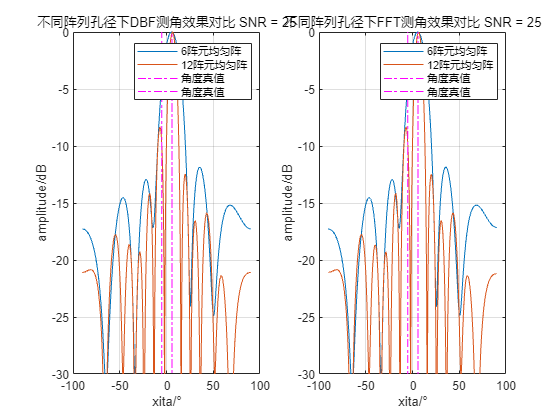

clear all; clc; clf;
%构造阵列
arraylen1 = 6;    %19°的分辨率
arraylen2 = 12;   %9°的分辨率    那么设置目标角度为12°？
array1 = 0:1:arraylen1-1;     
array2 = 0:1:arraylen2-1;     

%构造信号
theta = [-5, 6];  %多个目标时？

dd     = 0.5;   %均匀间隔
snap   = 1;     %快拍数
snr    = 25; 

numstarget = length(theta);
S = rand(numstarget,snap);

A_array1 = exp(-1i*2*pi*dd*sind(theta).*array1.'); x_array1 = A_array1*S;  x_array1 = awgn(x_array1,snr); 
A_array2 = exp(-1i*2*pi*dd*sind(theta).*array2.');  A_array2 = awgn(A_array2,snr);  x_array2 = A_array2*S;  x_array2 = awgn(x_array2,snr); 
%很奇怪的是，fft的测角和DBF的测角，会导致角度相反？这里加-1 后面应该用ifft才对？


%使用dbf测角
thetascan_dbf = linspace(-90,90,1024);
a_array2 = exp(1i*2*pi*dd*sind(thetascan_dbf).'*array2);
a_array1 = exp(1i*2*pi*dd*sind(thetascan_dbf).'*array1);

p_array1 = x_array1.'*a_array1.';  p_array1 = 20*log10(abs(p_array1)./max(abs(p_array1)));
p_array2 = x_array2.'*a_array2.';  p_array2 = 20*log10(abs(p_array2)./max(abs(p_array2)));


%使用FFT测角
fftlen = 1024;
thetascan_fft = linspace(-90,90,fftlen);    
fftout1 = fftshift(ifft(x_array1,fftlen));  fftout1 = 20*log10(abs(fftout1)./(max(abs(fftout1))));
fftout2 = fftshift(ifft(x_array2,fftlen));  fftout2 = 20*log10(abs(fftout2)./(max(abs(fftout2))));
xaxis   = asind((thetascan_fft./180)./dd);    %需要改变横坐标


%画图
figure(1)
subplot(121)
plot(thetascan_dbf,p_array1);hold on;
plot(thetascan_dbf,p_array2);
plot([theta(1),theta(1)],ylim,'m-.');plot([theta(2),theta(2)],ylim,'m-.');
xlabel('xita/°');ylabel('amplitude/dB');title(['不同阵列孔径下DBF测角效果对比 SNR = ' num2str(snr)]);
legend([num2str(arraylen1),'阵元均匀阵'],[num2str(arraylen2) '阵元均匀阵'], '角度真值', '角度真值');
hold off; grid on;ylim([-30,0]);


subplot(122)
plot(xaxis,fftout1);hold on;plot(xaxis,fftout2);
plot([theta(1),theta(1)],ylim,'m-.');plot([theta(2),theta(2)],ylim,'m-.');
xlabel('xita/°');ylabel('amplitude/dB');title(['不同阵列孔径下FFT测角效果对比 SNR = ' num2str(snr)]);
legend([num2str(arraylen1),'阵元均匀阵'],[num2str(arraylen2) '阵元均匀阵'], '角度真值', '角度真值');
hold off; grid on;ylim([-30,0]);

## Capon与DBF测角效果对比 试试不同的快拍数

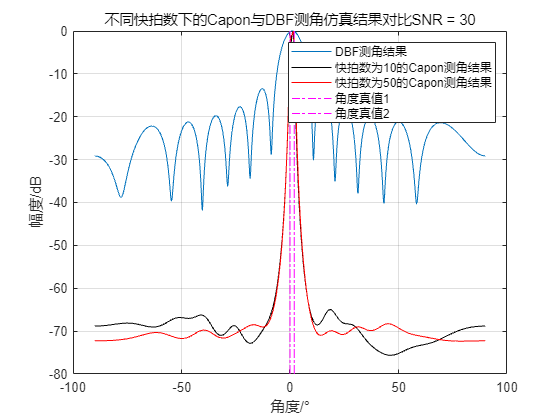

clear all; clc; clf;
%构造阵列
array    = linspace(0,11,12);
arraylen = length(array);
dd       = 0.5;

%构造目标
theta      = [0 2];
SNR        = 30;
numstarget = length(theta);

%构造回波信号   两个不同的快拍数
snap1    = 20;
snap2    = 100;
S1       = rand(numstarget,snap1)+1;
signal1  = exp(1i*2*pi*dd*sind(theta).'*array);  signal1 = signal1.'*S1;  signal1 = awgn(signal1,SNR);
S2       = rand(numstarget,snap2)+1;
signal2  = exp(1i*2*pi*dd*sind(theta).'*array);  signal2 = signal2.'*S2;  signal2 = awgn(signal2,SNR);


%分别使用DBF和capon测角   dbf时用一个快拍的数据即可。
theta_scan = linspace(-90,90,1024);
a          = exp(-1i*2*pi*dd*sind(theta_scan).'*array);

DBFresult1 = 20*log10(abs(signal1(:,1).'*a.')./(max(abs(signal1(:,1).'*a.'))));
% DBFresult2 = 20*log10(abs(signal2(:,1).'*a.')./(max(abs(signal2(:,1).'*a.'))));


R1 = inv(signal1*signal1'./snap1);   %这里需要是共轭转置！！
R2 = inv(signal2*signal2'./snap2);
for ii = 1:length(theta_scan)
    aa =  exp(-1i*2*pi*dd*sind(theta_scan(ii)).*array);
    caponresult1(ii) = 1/(abs(aa*R1*aa'));
    caponresult2(ii) = 1/(abs(aa*R2*aa'));
end
caponresult1 = 20*log10(caponresult1./max(caponresult1));
caponresult2 = 20*log10(caponresult2./max(caponresult2));


figure(1);
% subplot(121);
plot(theta_scan,DBFresult1);hold on;
plot(theta_scan,caponresult1,'k');plot(theta_scan,caponresult2,'r');
plot([theta(1),theta(1)],ylim,'m-.');plot([theta(2),theta(2)],ylim,'m-.');
title(['不同快拍数下的Capon与DBF测角仿真结果对比', 'SNR = ',num2str(SNR)]);
xlabel('角度/°');ylabel('幅度/dB');grid on; hold off;
legend('DBF测角结果','快拍数为10的Capon测角结果','快拍数为50的Capon测角结果','角度真值1','角度真值2');



% subplot(122);
% plot(theta_scan,DBFresult2);hold on;
% plot(theta_scan,caponresult2);
% title(['Capon与DBF测角仿真结果对比', '快拍数为： ',num2str(snap2),' SNR = ',num2str(SNR)]);


## Music & ESPRIT 及其与DBF的对比 这里不再做快拍数的对比

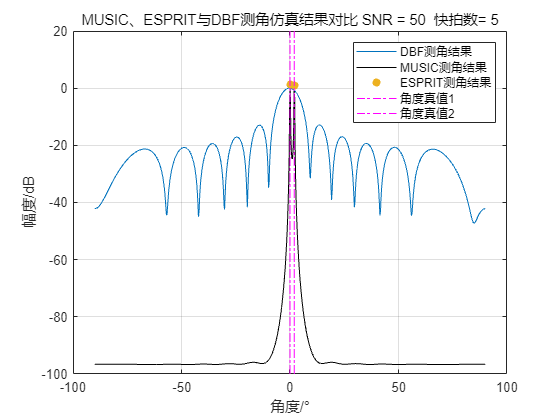

clear all; clc; clf;
%构造阵列
array    = linspace(0,11,12);
arraylen = length(array);
dd       = 0.5;

%构造目标
theta      = [0 2];
SNR        = 50;
numstarget = length(theta);
target2search = 2;

%构造回波信号   两个不同的快拍数
snap    = 5;
S       = randn(numstarget,snap);
signal  = exp(1j*2*pi*dd*sind(theta).'*array);  signal = signal.'*S;  signal = awgn(signal,SNR);



%使用DBF、MUSIC、ESPRIT测角   dbf时用一个快拍的数据即可。
theta_scan = linspace(-90,90,720);
% theta_scan = (-90:90);

%DBF
a          = exp(-1j*2*pi*dd*sind(theta_scan).'*array);
DBFresult  = 20*log10(abs(signal(:,1).'*a.')./(max(abs(signal(:,1).'*a.'))));

%MUSIC
R      =  signal*signal'/snap;
% INVR   =  inv(R);     %求逆【这里求逆的意义在哪？】
[EV,D] =  eig(R);     %特征值分解,D为由INVR的特征值构成的对角矩阵，EV为其特征向量构成的矩阵  【这里是对协方差矩阵的分解！】
EVA    =  diag(D)';   %抽取D的对角线元素并转置
[EVA,I] = sort(EVA);  %从小到大排序，I对应EVA中元素在原来EVA中的位置。
EVA    = fliplr(EVA); %对特征值再从大到小排列
EV     = fliplr(EV(:,I));  %对特征值对应的特征向量进行对应的从大到小的排序

EN     = EV(:,target2search+1:arraylen);   %把噪声子空间拿出来

for ii = 1:length(theta_scan)
    
    aa = exp(1j*2*pi*dd*sind(theta_scan(ii))*array).';
    MUSICresult(ii) = (aa'*aa)/(aa'*EN*EN'*aa);    %谱函数？也有其分子为1的，差别不大，反正都是常数。
%     MUSICresult(ii) =  1/(aa'*EN*EN'*aa);
end

MUSICresult = 20*log10(abs(MUSICresult)./(max(abs(MUSICresult))));


%ESPRIT
[EV2,D2]  = eig(R);            %直接对协方差矩阵的特征值分解？ D2为由R的特征值构成的对角矩阵，EV2为其特征向量构成的矩阵
EVA2      = real(diag(D2)');   %抽取D2的对角线元素并转置 
[EVA2,I2] = sort(EVA2);        %从小到大排序，I2对应EVA2中元素在原来EVA2中的位置。
EVA2      = fliplr(EVA2);      %对特征值再从大到小排列
EV2       = fliplr(EV2(:,I2)); %对特征值对应的特征向量进行对应的从大到小的排序

Exy   = [EV2(1:arraylen-1,1:target2search)  EV2(2:arraylen,1:target2search)];   %左右拼接
E_xys = Exy'*Exy./(size(Exy'*Exy,1));   %新的协方差矩阵？？ 这里不需要除吗？
[EV3,D3] = eig(E_xys);
EVA_xys  = real(diag(D3)');
[EVA_xys,I3] = sort(EVA_xys);
EVA_xys      = fliplr(EVA_xys);
EV_xys       = fliplr(EV3(:,I3));

%又是一个新的协方差矩阵？？
Gx  = EV_xys(1:target2search,target2search+1:target2search*2);
Gy  = EV_xys(target2search+1:target2search*2,target2search+1:target2search*2);
Psi = -Gx/Gy;
[EV4,D4] = eig(Psi);
EGS      = diag(D4)';
[EGS,I4] = sort(EGS);
EGS = fliplr(EGS);
EVS = fliplr(EV4(:,I4));

%角度
ephi  = atan2(imag(EGS),real(EGS));
angel = -asin(ephi/2/pi/dd)*180/pi;
estimate(1,:) = angel;
%功率
T = inv(EVS);
power = T*diag(EVA(1:target2search)-EVA(arraylen))*T';
power = abs(diag(power).')/arraylen;
estimate(2,:) = power;

ESPRITresult  = sort(estimate(1,:));


%画图
figure(1);
plot(theta_scan,DBFresult);hold on;
plot(theta_scan,MUSICresult,'k'); 
% plot(theta_scan,ESPRITresult,'r');
scatter(estimate(1,:),estimate(2,:),'filled');
plot([theta(1),theta(1)],ylim,'m-.');plot([theta(2),theta(2)],ylim,'m-.');
title(['MUSIC、ESPRIT与DBF测角仿真结果对比', ' SNR = ',num2str(SNR),'  快拍数= ',num2str(snap)]);
xlabel('角度/°');ylabel('幅度/dB');grid on; hold off;
legend('DBF测角结果','MUSIC测角结果','ESPRIT测角结果','角度真值1','角度真值2');

## DML&DBF

clear all; clc; clf;
%构造信号
%构造阵列
array    = linspace(0,11,12);
arraylen = length(array);
dd       = 0.5;

%构造目标
theta      = [0 1];
SNR        = 40;
numstarget = length(theta);
target2search = 2;

%构造回波信号   两个不同的快拍数
snap    = 1;
S       = randn(numstarget,snap);
signal  = exp(1j*2*pi*dd*sind(theta).'*array);  signal = signal.'*S;  signal = awgn(signal,SNR);


theta_scan1 = linspace(-90,90,1024);


%DBF
a          = exp(-1j*2*pi*dd*sind(theta_scan1).'*array);
DBFresult  = 20*log10(abs(signal(:,1).'*a.')./(max(abs(signal(:,1).'*a.'))));


%DML这里的算法只写了两个目标的。
R            =  signal*signal'/snap;

theta_scan    = linspace(sind(-90),sind(90),1024);
target_serched = zeros(1,target2search);
max_trace = intmin;
aa = zeros(length(array),target2search);

for ii = 1:length(theta_scan)
    aa(:,1) = exp(1i*2*pi*dd*array.'*theta_scan(ii));
    for jj = ii+1:length(theta_scan)                          %而且不能是同一个点？这两者不能相等
        aa(:,2) = exp(1i*2*pi*dd*array.'*theta_scan(jj));
        Pa = aa*(inv(aa'*aa))*aa';  
        Y = Pa*R;  
        tmp = abs(trace(Y));
        if tmp > max_trace
            target_serched(1) = theta_scan(ii);    
            target_serched(2) = theta_scan(jj);
            max_trace = tmp;
        end
    end
end

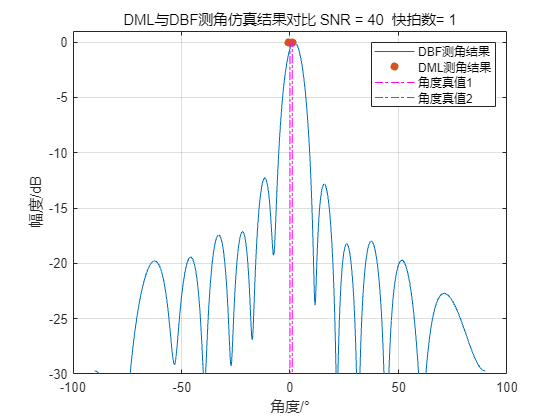



target_serched = asind(target_serched);


%画图
figure(1);
plot(theta_scan1,DBFresult);hold on;
scatter(target_serched,[0,0],'filled');
plot([theta(1),theta(1)],ylim,'m-.');plot([theta(2),theta(2)],ylim,'m-.');
title(['DML与DBF测角仿真结果对比', ' SNR = ',num2str(SNR),'  快拍数= ',num2str(snap)]);
xlabel('角度/°');ylabel('幅度/dB');grid on; hold off;
legend('DBF测角结果','DML测角结果','角度真值1','角度真值2');
ylim([-30 1]);

## OMP方法

clear all; clc; clf;
%构造阵列
array    = linspace(0,11,12);
arraylen = length(array);
dd       = 0.5;

%构造目标
theta      = [0 6];
SNR        = 35;
numstarget = length(theta);
target2search = length(theta);

%构造回波信号   两个不同的快拍数
snap    = 1;
S       = randn(numstarget,snap);
signal  = exp(1j*2*pi*dd*sind(theta).'*array);  signal = signal.'*S;  signal = awgn(signal,SNR);


theta_scan = linspace(-90,90,360);

%DBF
aa          = exp(-1j*2*pi*dd*sind(theta_scan).'*array);
DBFresult  = 20*log10(abs(signal(:,1).'*aa.')./(max(abs(signal(:,1).'*aa.'))));


%试一下归一化？
% for ii = 1:size(aa,1)
%     tmp = sqrt(sum(aa(ii,:).^2));
%     aa(ii,:) = aa(ii,:)./tmp;
% end

%OMP   代码似乎有点问题，后面应该好好看看。
aa = aa'; 
p  = arraylen;
K  = length(theta_scan);
L  = target2search;    %需要知道信源的个数(稀疏度)
for ii = 1:size(signal,2)
    a = [];
    x = signal(:,ii);  
    residual = x;      %初始化残差为信号
    indx = zeros(L,1);

    %需要做归一化的处理？
%{  
% old
    for jj = 1:L

        proj = aa'*residual;      %这里应该不需要加入之前已经找到了的位置吧！
        pos  = find(abs(proj) == max(abs(proj)));
        pos  = pos(1);
        indx(jj) = pos;
        a    = pinv(aa(:,indx(1:jj)))*x;      %Lp
        residual = x-aa(:,indx(1:jj))*a;   %计算残差？
    end
%}

%new

     buffer = aa;
     indexbuffer = (1:K);
     for jj = 1:L
        buffer = aa(:,setdiff(indexbuffer,indx));
        proj = buffer'*residual;      %这里应该不需要加入之前已经找到了的位置吧！
        pos  = find(abs(proj) == max(abs(proj)));
        pos  = pos(1);
        indx(jj) = pos;
        a    = pinv(buffer(:,indx(1:jj)))*x;      %Lp
        residual = x-buffer(:,indx(1:jj))*a;      %计算残差？
    end

    temp       = zeros(K,1);
    temp(indx) = a;
    A(:,ii)=sparse(temp);
end

A = full(A);
OMPresult = theta_scan(find(A~=0));

%画图
figure(1);
plot(theta_scan,DBFresult);hold on;
scatter(OMPresult,[0,0],'filled');
plot([theta(1),theta(1)],ylim,'m-.');plot([theta(2),theta(2)],ylim,'m-.');
title(['OMP与DBF测角仿真结果对比', ' SNR = ',num2str(SNR),'  快拍数= ',num2str(snap)]);
xlabel('角度/°');ylabel('幅度/dB');grid on; hold off;
legend('DBF测角结果','OMP测角结果','角度真值1','角度真值2');
% ylim([-30 1]);

## IAA的方法

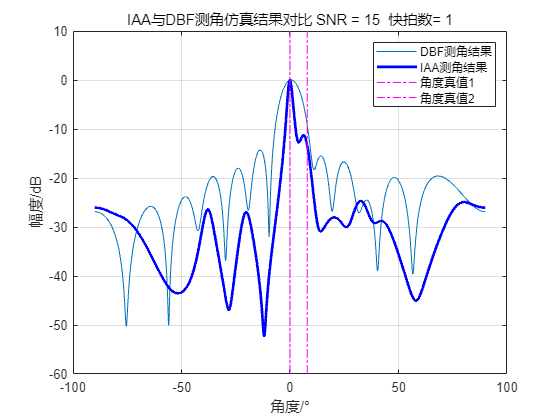

clear all; clc; clf;
%构造阵列
array    = linspace(0,11,12);
arraylen = length(array);
dd       = 0.5;

%构造目标
theta      = [0 8];
SNR        = 15;
numstarget = length(theta);
target2search = 2;

%构造回波信号   两个不同的快拍数
snap    = 1;
S       = randn(numstarget,snap);
signal  = exp(1j*2*pi*dd*sind(theta).'*array);  signal = signal.'*S;  signal = awgn(signal,SNR);


theta_scan = linspace(-90,90,1801);

%DBF
aa          = exp(-1j*2*pi*dd*sind(theta_scan).'*array);

DBFresult  = 20*log10(abs(signal(:,1).'*aa.')./(max(abs(signal(:,1).'*aa.'))));

%IAA
modulus_hat_das = sum(abs(aa*signal/arraylen),2 )/snap;
aa = aa';

threshold    = 1e-6;              %设置迭代的阈值？
maxIter      = 45;
[M thetaNum] = size(aa);
t_samples    = size(signal,2);
p_vec_Old    = abs(modulus_hat_das).^2;  
for iterIdx = 1:maxIter
    R     = aa * spdiags(p_vec_Old, 0, thetaNum, thetaNum) * aa';   % + sigma*eye(M);% R= R+mean(diag(R))*1e-12*eye(size(R,1));
    Rinv  = inv(R);
    p_vec = zeros(thetaNum, 1);
    for snapIdx = 1:t_samples
        y      = signal(:, snapIdx);
        Rinv_y = Rinv*y;
        Rinv_A = Rinv*aa;
        diag_A_Rinv_A = sum(conj(aa).*Rinv_A, 1).';
        coeff = aa'*Rinv_y./real(diag_A_Rinv_A);
        p_vec = p_vec + abs(coeff).^2;
    end
    p_vec = p_vec/t_samples;
    if norm(p_vec_Old-p_vec)/norm(p_vec_Old)<threshold
        break;
    end
    p_vec_Old = p_vec;
end
[~, index] = findpeaks(p_vec, 'sortstr', 'descend');
IAAresult  = coeff;  


%画图
figure(1);
plot(theta_scan,DBFresult);hold on;
plot(theta_scan,20*log10(abs(IAAresult)./max(abs(IAAresult)) + eps),'b','LineWidth',2);
plot([theta(1),theta(1)],ylim,'m-.');plot([theta(2),theta(2)],ylim,'m-.');
title(['IAA与DBF测角仿真结果对比', ' SNR = ',num2str(SNR),'  快拍数= ',num2str(snap)]);
xlabel('角度/°');ylabel('幅度/dB');grid on; hold off;
legend('DBF测角结果','IAA测角结果','角度真值1','角度真值2');

% ylim([-30 1]);

## 阵列补全及其补全前后的测角效果对比 测角用DBF来测即可

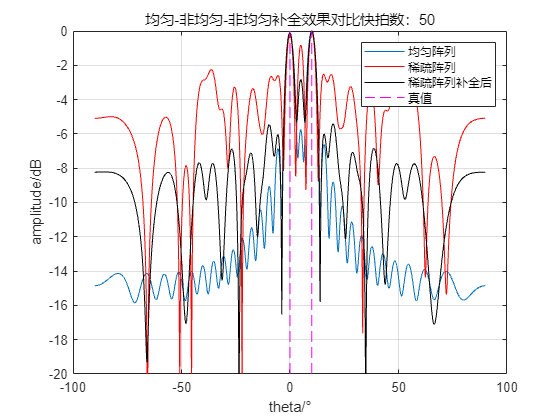

clear all; clc; clf;
%基于协方差矩阵向量化：
% array = [0 1 3];
% array = [0 1 4 6];
% array = [0 1 4 7 9];
% array = [0 1 2 6 10 13];
% array = [0 1 2 6 10 14 17];
% array = [0 1 2 11 15 18 21 23];
array = [0 1 2 14 18 21 24 27 29];
% array = [0 1 3 6 13 20 27 31 35 36];
% array = [0 1 3 6 13 20 27 34 38 42 43];
% array = [0 1 3 6 13 20 27 34 41 45 49 50]; 
% array = [0 1 2 3 27 32 36 40 44 48 52 55 58];
% array = [0 1 2 8 15 16 26 36 46 56 59 63 65 68];
% array = [0 1 2 5 10 15 26 37 48 59 65 71 77 78 79];
% array = [0 1 2 5 10 15 26 37 48 59 70 76 82 88 89 90];

% array = [0 2 5 7 10 11]; %非最小冗余阵试一试？
% array = [0 2 3 5 9 11];

%%给出没有空缺阵元的情况（与后面对比）  后续空缺的数据从这里取出对应的位置即可
array_uni = (0:1:array(end));

%构造信号
theta = [0 10];  % 待估计角度
num_targets =  length(theta);
                      
dd = 0.5;            % 均匀阵元间距设置 *λ 
A=exp(-1i*2*pi*dd*array_uni.'*sind(theta));   %方向矢量矩阵      通道数*信源数

K = 50;                       % 快拍数  
S=rand(num_targets,K);        % 产生正态分布的信源幅度？ 如果全是1的话 那和单快拍就没有区别了...

X=A*S;   %信号矩阵             %通道数*快拍数       
snr = 35;            % 信噪比
X=awgn(X,snr,'measured');  %将白色高斯噪声添加到信号中



%%非均匀阵列对应的信息：空缺的位置补0，从对应的位置把数据拿到（因为是多快拍这里在快拍维度取均值？ 或者不应该取均值？）
%对比看看取均值与只取一个快拍的效果

%需要补充将实际阵列的数据拿出来（空的位置补充0即可）
data_original2 = zeros(length(array),K);     %而且是 不要空缺元素地去求协方差矩阵
data_tmp = X;  
for ii = 1:length(array)
    data_original2(ii,:) = data_tmp(array(ii)+1,:);
end

data_original1 = zeros(length(array_uni),K);  %这里data_original1是用来看看非均匀阵下有很多空缺元素时的测角效果
for ii = 1:length(array)
    data_original1(array(ii)+1,:) = data_tmp(array(ii)+1,:);
end

%%基于（空缺阵元的）协方差矩阵向量化的缺失信息补全
Rxx=data_original2*data_original2'/K; 

data_buffer = reshape(Rxx,1,(size(Rxx,1))^2);   %向量化   reshape是一列一列去取数据排序的

%向量化位置选取

% 差分集合的计算    在下面这种方法之下，差分集合(每个元素都减去集合中全部的元素)的元素个数与协方差元素的个数是相等的(啥意思？)。  
% 对于那些差分集合还是有很多空缺的稀疏阵列，那这种方法不适用补全全部的元素，不过最小冗余不需要考虑这个问题。
% 对于互质和嵌套应该也是能将中间空缺的全部补全？

L = length(array);
for jj=1:L    %求差分集合
       B11(1+(jj-1)*L:jj*L)=array(jj)-array(:);  %每个元素都减去集合中全部的元素。 这里是负数也没关系？负数和对应的正数会成对存在，所以下面除以2
end                                              %但是要注意这里对差分阵列集合的求解方法，需要与后面矩阵位置选取时一样！  
                                                 %这里也等价于是按照前述协方差矩阵中列的方式在求差分集合。

%找到集合中唯一的值,且已排序(Val对应的是集合中的唯一的元素的值，顺序从小到大，indu对应该值第一次出现的索引值)。（其实对于最小冗余来说？绝大多数都是唯一的？除去0）
[val,indU] =unique(B11);
% fprintf('向量长度=%d\n',length(indU));
ndU=length(indU);    %非重复元素的个数(包括有0)

%找到恢复后的均匀阵列元素
% data_recovered = data_buffer(indU((ndU+1)/2:end));   
%差分集合中必定正负数的数量是一样的，此外还有通道个数个0。
%这里的indu对应的因为是取了unique，于是0只有一个，那么数量上ndu必定是奇数。抛弃一半(且是从小到大排序，于是从0开始取后面的值)于是要加1除以2。

%如果有空缺的位置？
data_recovered = zeros(1,array(end)+1);   %尽量恢复成全部都是均匀的，但是也有可能有一些没有啊！
data_recovered(val((ndU+1)/2:end)+1) = data_buffer(indU((ndU+1)/2:end));


%%画图比较效果
xita_scan = (-90:0.1:90);

a = exp(1i*2*pi*dd*array_uni.*sind(xita_scan).');
p_uni = a*sum(X,2)/K;
p_ununi = a*sum(data_original1,2)/K.';
p_repair = a*data_recovered';

%归一化
p_uni = 10*log10(abs(p_uni)./max(abs(p_uni)));
p_ununi = 10*log10(abs(p_ununi)./max(abs(p_ununi)));
p_repair = 10*log10( abs(p_repair)./ max(abs(p_repair)) );


figure(101);
plot(xita_scan,p_uni);hold on;plot(xita_scan,p_ununi,'r'); plot(xita_scan,p_repair,'k'); ylim([-20,0]);
xlabel('theta/°');ylabel('amplitude/dB');title(['均匀-非均匀-非均匀补全效果对比','快拍数：' ,num2str(K)]);
for jj = 1:length(theta)
    plot([theta(jj),theta(jj)],ylim,'m--');
end
legend('均匀阵列','稀疏阵列','稀疏阵列补全后','真值');grid on; hold off;

## 基于SVT算法 和Hankel矩阵以及Toeplitz矩阵

clear all; clc; clf;
%一种新的矩阵填充方法
%%对于一维的阵列，其实将该一维阵列填充成矩阵的方法不止一种？文献中给出的hankel形式矩阵只是其中的一种填充方法。

clear all,close all,clc;

% d=[1,4,5,6,9,12,14,15,21,24,25,26,29,32,34,35,41,44,45,46,49,52,54,55,61,64,65,66,69,72,74,75,81,84,85,86,89,92,94,95,101,104,105,106,109,112,114,115]-1;
d = [0 1 2 11 15 18 21 23 24];  %最后一个需要是偶数？
% d = [0 2 5 7 10 12];
arrayuni = (0:1:d(end));
theata_target = [0 5];    %目标方向
K = length(theata_target);    %目标个数
S = ones(K,1)+1; %目标信号幅度
A = exp(1j*pi*arrayuni.'*sind(theata_target));    %方向矢量矩阵
X_uni = A*S;       %接收的单快拍信号
snr = 35;
X_uni  = awgn(X_uni,snr,'measured');   %加白噪声后的信号
X_real = X_uni(d+1); 


%%稀疏阵列与对应均匀阵列的常规波束成形
theta_scan    = linspace(-90,90,1801);
scan_az_uni  = exp(-1i*pi*sind(theta_scan).'*arrayuni);
scan_az_real = exp(-1i*pi*sind(theta_scan).'*d);
out_uni  = scan_az_uni*X_uni;
out_real = scan_az_real*X_real;
out_uni  = 20*log10(abs(out_uni)./max(abs(out_uni)));
out_real = 20*log10(abs(out_real)./max(abs(out_real)));
figure;
plot(theta_scan,out_uni);  
hold on;
plot(theta_scan,out_real);


%%基于Hankel矩阵的恢复
M    = d(end)-d(1)+1; 
tic
temp1 = ha(M,d+1,X_real);
toc

历时 0.045330 秒。



out_hankel = scan_az_uni*temp1.';
out_hankel = 20*log10(abs(out_hankel)/max(abs(out_hankel)));
plot(theta_scan,out_hankel);


%%基于Toeplitz矩阵的方法：  这种方法用到的还是SVT的方法去恢复矩阵，只是和Hankel填充的方法不一样。
%这里是构造一个大的(行列数为阵列总长度对应的均匀阵元的数目)矩阵，并往里头基于已有的阵元填充一个Toeplitz矩阵  
%这样的话，反思一下，是否也可以构造一个大的hankel矩阵？比如左上部分填充原始数据，右下部分填充对应的共轭数据？

% dd=[0 1 2 5 10 15 26 37 48 59 70 81 87 93 99 100 101 102 104 107 111 114];
dd = 0:d(end);             %是均匀阵列时对应的是Toeplitz的方法？
NN = length(dd);
array_data = zeros(NN,NN);

for ii = 1:NN
    for jj = 1:NN
        array_data(ii,jj) = dd(ii)-dd(jj);
    end
end

[val,indU] = unique(array_data);
array_data(indU);
data = zeros(NN,NN);
for ii = 1:length(d)
   data(array_data==d(ii)) = X_real(ii);           %将data中对应反对角线位置的元素用测量数据填充
   data(array_data==(-d(ii))) = conj(X_real(ii));  %关于主对角线对称位置的元素用复共轭来填充
end

P_Indx = (data~=0);  %Mask  data这个矩阵中有数据的地方用1来填充没有数据的地方用0填充
T=5*NN;
delta=2;
tic
[data_completed,iterations]=SVT(data,P_Indx,T,delta,500,1e-6);
toc

历时 0.131985 秒。


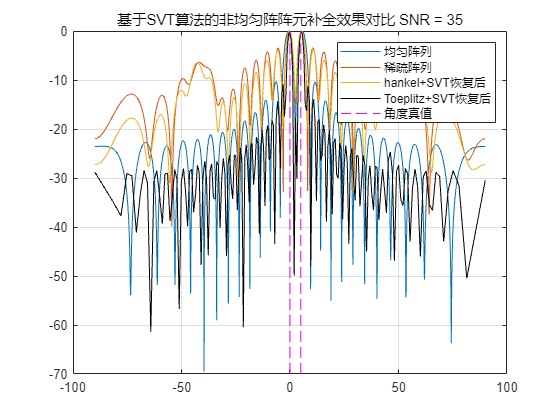

MM=2*max(d)+1;  %这里就是之前说的可以增加一倍的角分辨率？
temp2=zeros(1,MM);

for ii=1:MM
   if sum(sum(array_data==(ii-max(d)-1)))~=0
       temp2(ii)=mean(mean(data_completed(array_data==(ii-max(d)-1))));  %这里是不是多了一个mean
   end
end

out2=fftshift(fft(temp2,181,2),2);
out2_log=20*log10(abs(out2)./max(abs(out2)));
plot(asind(linspace(-1,1,181)),out2_log,'k');

for jj = 1:length(theata_target)
    plot([theata_target(jj),theata_target(jj)],ylim,'m--');
end


legend('均匀阵列','稀疏阵列','hankel+SVT恢复后','Toeplitz+SVT恢复后','角度真值');grid on;
title(['基于SVT算法的非均匀阵阵元补全效果对比', ' SNR = ',num2str(snr)]);

## 2D-DOA估计

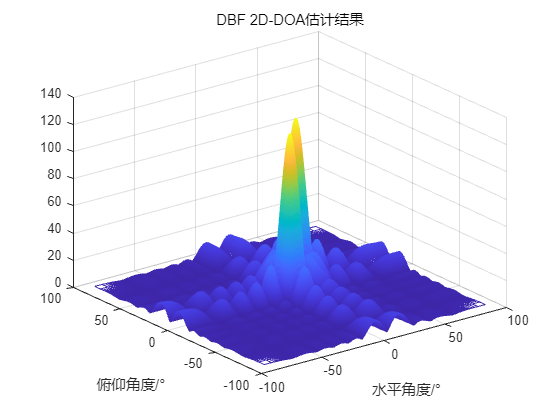

clear all; clc; clf;
%2D矩形面阵   不需要做角度匹配。
%构造信号
theta_target = [0 0;20 20];   %目标来波方向，每一行对应一个目标。 这里的角度对应为与x轴和y轴的夹角。
nums_target = size(theta_target,1);
amplitude = ones(1,nums_target);
dd_azi = 0.5;
dd_ele = 0.5;

array_azi = 0:1:10; Len_azi = length(array_azi);
array_ele = 0:1:10; Len_ele = length(array_ele);
signals_orginal = zeros(Len_ele,Len_azi);
for ii = 1:nums_target
    for jj = 1:Len_ele
        for kk = 1:Len_azi
            signals_orginal(jj,kk) = signals_orginal(jj,kk) + amplitude(ii)* exp( 1i*2*pi* (dd_azi*(array_azi(kk)*sind(theta_target(ii,1)))+dd_ele*array_ele(jj)*sind(theta_target(ii,2))));
        end
    end
end

%直接2D-fft处理和画图
theta_index_azi=(-90:0.5:90)/180; 
theta_index_ele=(-90:0.5:90)/180; 
x_axis = asind(1/dd_azi*theta_index_azi);
y_axis = asind(1/dd_ele*theta_index_ele);

data_dbf   = signals_orginal;
fftOut_dbf = fftshift(fft(data_dbf,length(theta_index_azi),2),2);
fftOut_dbf = fftshift(fft(fftOut_dbf,length(theta_index_ele),1),1);

figure(1)
mesh(x_axis,y_axis,abs(fftOut_dbf));
title('DBF 2D-DOA估计结果');xlabel('水平角度/°');ylabel('俯仰角度/°');

function XX=ha(M,array,X)
%%hankel恢复
y = zeros(M,1);   %对应均匀阵列应该接收的信号，先置0，之后往里头填充进去对应实际阵列中位置的接收信号
for i = 1:length(array)
    y(array(i)) = X(i);
end

N = (M+1)/2;  %汉克尔矩阵的长度   如果M是偶数？？
Hankel_matrix = zeros(N,N);
P_Indx = zeros(N,N);
for ii=1:N
    for jj=1:N
        Hankel_matrix(ii,jj)=y(ii+jj-1);   %填充
        if norm(Hankel_matrix(ii,jj))~=0
            P_Indx(ii,jj)=1;    %有的地方为1 没有的保持为0
        end
    end
end


%将前述得到的汉克尔矩阵以及对应的标志矩阵给到SVT里头
% T=5*sqrt(N*N); delta =3 ;
T=5*sqrt(N*N); delta =2;
[Hankel_completed,iterations] = SVT(Hankel_matrix,P_Indx,T,delta);

%基于得到的矩阵，得到其对应均匀阵元的等效接收数据：反对角线元素取均值并排序
XX = zeros(1,M);
for ii=1:N
    for jj=1:N
         XX(ii+jj-1)=XX(ii+jj-1)+Hankel_completed(ii,jj);   %索引值相加相等的元素
    end
end
XX(1:N)=XX(1:N)./(1:N);
XX(N+1:end)=XX(N+1:end)./(N-1:-1:1);
end




function [ X,iterations ] = SVT(M,P,T,delta,itermax,tol)
%处理图像时传进来了四个量：M对应原有的矩阵   P为欠采样的矩阵   T=5000  delta = 1

%Single value thresholding algorithm，SVT
% function：solve the following optimization problem
%                  min  ||X||*
%               s.t. P(X-M) = 0
% X: recovered matrix
% M: observed matrix
% T: single value threshold
% delta: step size
% output：X,iterations

% initialization
Y = zeros(size(M));
iterations = 0;

if nargin < 3
    T =  sqrt(n1*n2);
end
if nargin < 4
    delta = 1;
end


if nargin < 5
    itermax = 200;
end
if nargin < 6
    tol = 1e-7;  %阈值  小于该值认为完成了复原
end

for ii = 1:itermax    %最多进行的迭代次数
    % singular value threshold operation
    [U, S, V] = svd(Y, 'econ') ; %奇异值分解：Y = U*S*V'  Y对应的就是汉克尔矩阵？N*N  U是导向矢量流阵N*K   S是信号幅度K*1  V=U' K*N
    S = sign(S) .* max(abs(S) - T, 0) ;   %sign是得到S的符号？：1、0、-1   
    X = U*S*V' ;  %重新构造的矩阵？ 也是要传出去的矩阵啊！

    % update auxiliary matrix Y     Y可以说是一个辅助矩阵
    Y = Y + delta*  P.* (M-X);   %P是欠采样的矩阵  M是原始矩阵   P.* (M-X)实际上是把对应采样点的数据拿出来
    Y = P.*Y ;
    % computer error
    error= norm( P.* (M-X),'fro' )/norm( P.* M,'fro' ); %返回矩阵的2-范数或最大奇异值   
    if error<tol    %这个值在9e-5的样子就可以保证后面很不错了？  甚至0.05也可？
        break;
    end
    % update iterations
    iterations = ii ;  %迭代了多少次？
end
end

%}



%---------------------------------------------------------------------------------------%